close all
clear
clc

准备工作

[t,omg,FT,IFT] = prefourier([-3,3],1000,[-15,15],1000);

生成理想低通滤波器的频响，包括幅频和相频

omgc = 10;
t0 = 1;
H_abs = ((omg<omgc)&(omg>-omgc));
H = H_abs.*exp(-1j*t0*omg);

逆变换得到冲激响应

h = IFT*H;

对冲激响应积分得到阶跃响应

g = (t(2)-t(1))*cumsum(h);

绘图

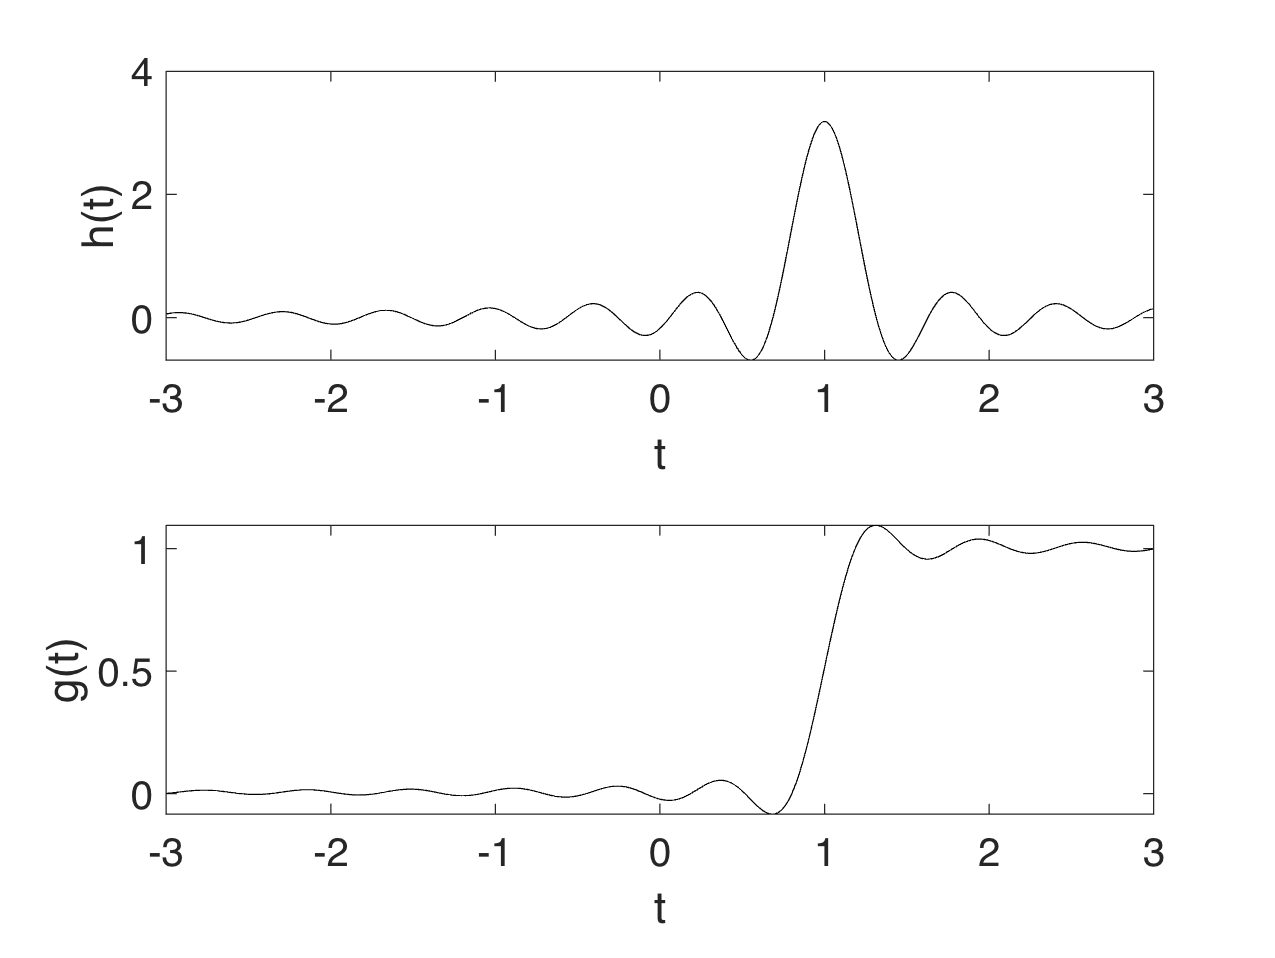

figure;
subplot(2,1,1), box on, hold on;
plot(t, real(h), 'k-');
set(gca,'FontSize',16);
xlabel('t');
ylabel('h(t)');
subplot(2,1,2), box on, hold on;
plot(t, real(g), 'k-');
set(gca,'FontSize',16);
xlabel('t');
ylabel('g(t)');